clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

MixedFP = obj.MixedFP;


hd_control = cell(3, 2);
hd_chemo = cell(3, 2);
rt_control = cell(3, 2);
rt_chemo = cell(3, 2);

pd_rt_control = cell(3, 2);
pd_rt_chemo = cell(3, 2);
pd_rt_control_ci = cell(3, 2);
pd_rt_chemo_ci = cell(3, 2);

pd_hd_control = cell(3, 2);
pd_hd_chemo = cell(3, 2);
pd_hd_control_ci = cell(3, 2);
pd_hd_chemo_ci = cell(3, 2);

cd_hd_control = cell(3, 2);
cd_hd_chemo = cell(3, 2);
cd_hd_control_ci = cell(3, 2);
cd_hd_chemo_ci = cell(3, 2);


bins = 0:0.001:2;
band_width = 0.05;
n_boot = 1000;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_cdf = @(x) ksdensity(x, bins, 'Function', 'cdf', 'Bandwidth', band_width);


valid = 0;
for fp = 1:3
    for p = 1:2

        hd_control{fp, p} = obj.HDSortedControl{fp, p};
        hd_chemo{fp, p} = obj.HDSortedChemo{fp, p};
        switch valid
            case 1
                hd_control{fp, p} = hd_control{fp, p}(hd_control{fp, p}>0.5);
                hd_chemo{fp, p} = hd_chemo{fp, p}(hd_chemo{fp, p}>0.5);
        end
        
        rt_control{fp, p} = hd_control{fp, p} - MixedFP(fp);
        rt_chemo{fp, p} = hd_chemo{fp, p} - MixedFP(fp);

        rt_control{fp, p} = rt_control{fp, p}(rt_control{fp, p}>0.05 & rt_control{fp, p}<2);
        rt_chemo{fp, p} = rt_chemo{fp, p}(rt_chemo{fp, p}>0.05 & rt_chemo{fp, p}<2);

    end
end


for fp = 1:3
    for p = 1:2

        disp([fp, p]);

%         pd_rt_control{fp, p} = kde_pdf(rt_control{fp, p});
%         pd_rt_chemo{fp, p} = kde_pdf(rt_chemo{fp, p});
%         pd_rt_control_ci{fp, p} = bootci(n_boot, {kde_pdf, rt_control{fp, p}}, 'type', 'cper');
%         pd_rt_chemo_ci{fp, p} = bootci(n_boot, {kde_pdf, rt_chemo{fp, p}}, 'type', 'cper');

        pd_hd_control{fp, p} = kde_pdf(hd_control{fp, p});
        pd_hd_chemo{fp, p} = kde_pdf(hd_chemo{fp, p});
        pd_hd_control_ci{fp, p} = bootci(n_boot, {kde_pdf, hd_control{fp, p}}, 'type', 'cper');
        pd_hd_chemo_ci{fp, p} = bootci(n_boot, {kde_pdf, hd_chemo{fp, p}}, 'type', 'cper');

        cd_hd_control{fp, p} = kde_cdf(hd_control{fp, p});
        cd_hd_chemo{fp, p} = kde_cdf(hd_chemo{fp, p});
        cd_hd_control_ci{fp, p} = bootci(n_boot, {kde_cdf, hd_control{fp, p}}, 'type', 'cper');
        cd_hd_chemo_ci{fp, p} = bootci(n_boot, {kde_cdf, hd_chemo{fp, p}}, 'type', 'cper');
    end
end

     1     1
     1     2
     2     1
     2     2
     3     1
     3     2


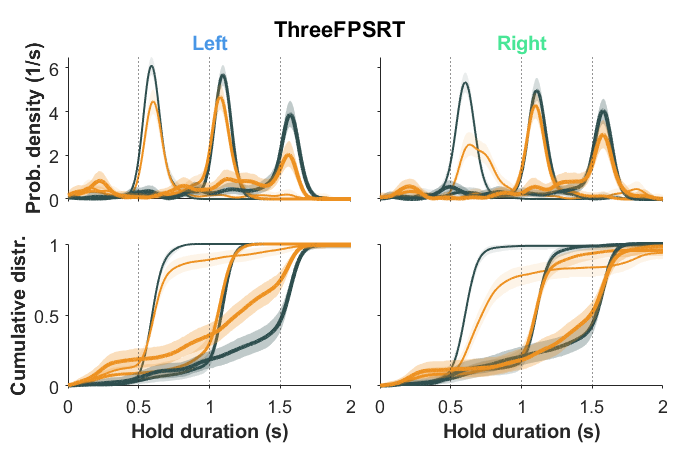

fig_hd = figure(34); clf(34);
set(fig_hd, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 8], 'Color', 'w');

set_fig_title(fig_hd, 'ThreeFPSRT', 'FontSize', 11);

ax = cell(2,2);

for p = 1:2

    ax{1,p} = axes(fig_hd, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 4.5 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
    ax{2,p} = axes(fig_hd, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 1.2 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    for fp = 1:3
        xline(ax{1,p}, MixedFP, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax{1,p}, [bins flip(bins)], [pd_hd_control_ci{fp, p}(1,:) flip(pd_hd_control_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{1,p}, bins, pd_hd_control{fp, p}, ...
            'color', GPSColor.Control, 'linewidth', .5+.5*fp, 'LineStyle', '-');
        fill(ax{1,p}, [bins flip(bins)], [pd_hd_chemo_ci{fp, p}(1,:) flip(pd_hd_chemo_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{1,p}, bins, pd_hd_chemo{fp, p}, ...
            'color', GPSColor.Treat  , 'linewidth', .5+.5*fp, 'LineStyle', '-');


        xline(ax{2,p}, MixedFP, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax{2,p}, [bins flip(bins)], [cd_hd_control_ci{fp, p}(1,:) flip(cd_hd_control_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{2,p}, bins, cd_hd_control{fp, p}, ...
            'color', GPSColor.Control, 'linewidth', .5+.5*fp, 'LineStyle', '-');
        fill(ax{2,p}, [bins flip(bins)], [cd_hd_chemo_ci{fp, p}(1,:) flip(cd_hd_chemo_ci{fp, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
        plot(ax{2,p}, bins, cd_hd_chemo{fp, p}, ...
            'color', GPSColor.Treat  , 'linewidth', .5+.5*fp, 'LineStyle', '-');

        drawnow;
    end
end

ax{1,1}.YLabel.String = "Prob. density (1/s)";
ax{1,1}.YLabel.FontWeight = "bold";

ax{1,1}.Title.String = "Left";
ax{1,1}.Title.Color = GPSColor.PortL;
ax{1,1}.Title.FontWeight = "bold";

ax{1,2}.Title.String = "Right";
ax{1,2}.Title.Color = GPSColor.PortR;
ax{1,2}.Title.FontWeight = "bold";

ax{1,1}.YLim(2) = max([ax{1,1}.YLim(2) ax{1,2}.YLim(2)]);
ax{1,1}.YLim(2) = .5 * (ceil(ax{1,1}.YLim(2)) + round(ax{1,1}.YLim(2)));
ax{1,2}.YLim(2) = ax{1,1}.YLim(2);

set(ax{1,1}, 'XLim', [0 2], 'XTickLabel', []);
set(ax{1,2}, 'XLim', [0 2], 'XTickLabel', [], 'YTickLabel', []);

ax{2,1}.XLabel.String = "Hold duration (s)";
ax{2,1}.YLabel.String = "Cumulative distr.";
ax{2,1}.XLabel.FontWeight = "bold";
ax{2,1}.YLabel.FontWeight = "bold";

ax{2,2}.XLabel.String = "Hold duration (s)";
ax{2,2}.XLabel.FontWeight = "bold";

set(ax{2,1}, 'XLim', [0 2]);
set(ax{2,2}, 'XLim', [0 2], 'YTickLabel', []);

switch valid
    case 0
        fig_name = sprintf("Test_%s_Distr_3FP_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Distr_3FP_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd, fig_path, 'Resolution', 600);

% fig_rt = figure(35); clf(35);
% set(fig_rt, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 11.2], 'Color', 'w');
% 
% set_fig_title(fig_rt, 'ThreeFPSRT', 'FontSize', 11);
% 
% ax = cell(3,2);
% 
% for p = 1:2
% 
%     for fp = 1:3
%         ax{fp,p} = axes(fig_rt, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 10.5-3*fp 5 2.5], ...
%             'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
%         fill(ax{fp,p}, [bins flip(bins)], [pd_rt_control_ci{fp, p}(1,:) flip(pd_rt_control_ci{fp, p}(2,:))], 'y', ...
%             'FaceColor', GPSColor.Control, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
%         plot(ax{fp,p}, bins, pd_rt_control{fp, p}, ...
%             'color', GPSColor.Control, 'linewidth', .5+.5*fp, 'LineStyle', '-');
%         fill(ax{fp,p}, [bins flip(bins)], [pd_rt_chemo_ci{fp, p}(1,:) flip(pd_rt_chemo_ci{fp, p}(2,:))], 'y', ...
%             'FaceColor', GPSColor.Treat, 'FaceAlpha', .1*fp, 'EdgeColor', 'none');
%         plot(ax{fp,p}, bins, pd_rt_chemo{fp, p}, ...
%             'color', GPSColor.Treat  , 'linewidth', .5+.5*fp, 'LineStyle', '-');
% 
%         set(ax{fp,p}, 'XLim', [0 1]);
%         if fp==3
%             ax{fp,p}.XLabel.String = "Hold duration (s)";
%             ax{fp,p}.XLabel.FontWeight = "bold";
%         else
%             set(ax{fp,p}, 'XTickLabel', []);
%         end
%         if fp==1
%             switch p
%                 case 1
%                     ax{fp,p}.Title.String = "Left";
%                     ax{fp,p}.Title.Color = GPSColor.PortL;
%                 case 2
%                     ax{fp,p}.Title.String = "Right";
%                     ax{fp,p}.Title.Color = GPSColor.PortR;
%             end
%             ax{fp,p}.Title.FontWeight = "bold";
%         end
%         if p==1
%             if fp==3
%                 ax{fp,p}.YLabel.String = "Prob. density (s^{-1})";
%                 ax{fp,p}.YLabel.FontWeight = "bold";
%             end
%         else
%             set(ax{fp,p}, 'YTickLabel', []);
%             % 
%             ax_legend = axes(fig_rt, 'Units', 'centimeters', 'Position', ax{fp,p}.Position, ...
%                 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
%                 'Color', 'none', 'XColor', 'none', 'YColor', 'none');
%             text(ax_legend, .65, .9, sprintf('FP = %.1f s', MixedFP(fp)), 'FontSize', 9, 'FontWeight', 'bold');
%             set(ax_legend, 'XLim', [0 1], 'YLim', [0 1]);
%         end
% 
%         drawnow;
%     end
% end
% 
% y_limit = max(max(cellfun(@(x) x.YLim(2), ax)));
% y_limit = .5 * (ceil(y_limit) + round(y_limit));
% for fp=1:3
%     for p=1:2
%         ax{fp,p}.YLim(2) = y_limit;
%     end
% end
% 
% fig_name = sprintf("Test_%s_RT_Distr_3FP_%s.jpg", obj.Task, obj.Subject);
% fig_path = fullfile(FigFolder, fig_name);
% exportgraphics(fig_rt, fig_path, 'Resolution', 600);
